# Pulse tests to verify model

## 1. Importing raw data

The measurements were saved in an excel spreadsheet, the table was imported in Matlab 

clear all
close all
load batpulsemeas.mat
% figure()
% set(gcf,'color','w');
% subplot(2,1,2)
% plot(samples)
% subplot(2,1,1)
% plot(voltage,'x')

First, we will set the time

t=0 goes to sample #251

the sampling frequency is 2.066Hz

% time=(samples'-251)/2.066;

sample 1491 corresponds to the end of charging at C/5

At sample 1822 there is a reset in memory, so there is a gap in measurements

sample 2807 is 21 minutes, the total duration should be around 11minutes ~ 660sec

% (2807-1491)/2.066

but this is only 636sec saved

% 660*2.066

This should be 1363 samples, but there are only 1316, so, 47 samples are missing

Second gap: sample 3567...

and so on, here is the data:

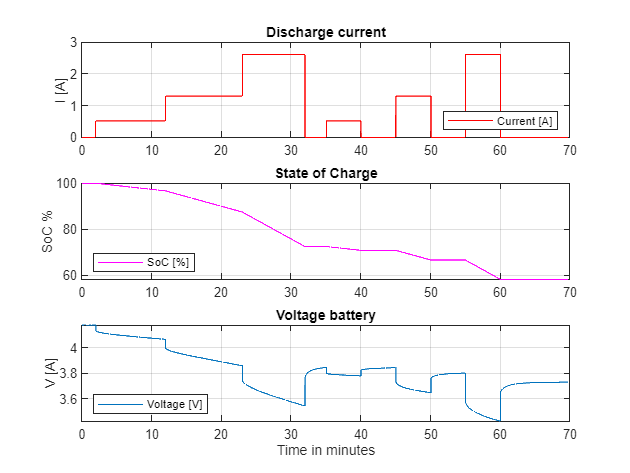

%time = zeros (1,length(samples));
time = zeros (1,8638);
for i = 1:1822
    time(i)=(samples(i)-251)/2.066;
end
%add first memory gap: 47 samples
for i = 1823:1:1823+47
     time(i)=(samples(1822)+i-1822-251)/2.066;
end
%fill second part
for i = 1871:3567+47
    time(i)=time(1870)+(samples(1822+i-1870))/2.066;
end
%add 2nd memory gap: 25 samples
for i = 3567+47+1:1:3567+47+1+25
     time(i)=time(3614)+(i-3614)/2.066;
end
%fill 3rd part
for i = 3567+47+1+25:1:3640+1576
    time(i)=time(3639)+(samples(3568+i-3640))/2.066;
end
%add 3rd memory gap: 40 samples
for i = 5215+1:1:5215+1+40
    time(i)=time(5215)+(i-5215)/2.066;
end
%fill 4th part
for i = 5255+1:1:5256+1+1437
    time(i)=time(5256)+(samples(5144+i-5256))/2.066;
end
%add 4th memory gap: 30 samples
for i = 6692+1:1:6693+1+30
    time(i)=time(6692)+(i-6692)/2.066;
end
%fill 5th part
for i = 6725:1:6725+1+1912
    time(i)=time(6724)+(samples(6581+i-6724))/2.066;
end

time=time-time(1);
% figure()
% plot (time)
%Voltage
V = zeros (1,8638);
for i = 1:1822
    V(i)=voltage(i);
end
%add first memory gap: 47 samples
for i = 1823:1:1823+47
    V(i)=0;
end
%fill second part
for i = 1871:3567+47
    V(i)=voltage(i-47);
end
%add 2nd memory gap: 25 samples
for i = 3567+47+1:1:3567+47+1+25
    V(i)=0;
end
%fill 3rd part
for i = 3567+47+1+25:1:3640+1576
    V(i)=voltage(i-47-25);
end
%add 3rd memory gap: 40 samples
for i = 5215+1:1:5215+1+40
    V(i)=0;
end
%fill 4th part
for i = 5255+1:1:5256+1+1437
    V(i)=voltage(i-47-25-40);
end
%add 4th memory gap: 30 samples
for i = 6692+1:1:6693+1+30
    V(i)=0;
end
%fill 5th part
for i = 6725:1:6725+1+1910
    V(i)=voltage(i-47-25-40-29);
end
V(8637)=V(8636);
V(8638)=V(8637);
%fill first memory gap: 47 samples
for i = 1823:1:1823+47
    V(i)=V(1822)+(V(1871)-V(1822))/47*(i-1822);
end
%add 2nd memory gap: 25 samples
for i = 3567+47+1:1:3567+47+1+25
    V(i)=V(3614)+(V(3641)-V(3614))/25*(i-3614);
end
%add 3rd memory gap: 40 samples
for i = 5215+1:1:5215+1+40
    V(i)=V(5215)+(V(5257)-V(5215))/40*(i-5215);
end
%add 4th memory gap: 30 samples
for i = 6692+1:1:6693+1+30
    V(i)=V(6692)+(V(6725)-V(6692))/30*(i-6692);
end
% figure()
% plot (V)

%% Current calculation
I=zeros(1,8638);
for i=250:1491
    I(i)=0.52;
end
for i=1492:2854
    I(i)=1.3;
end 
for i=2855:3968
    I(i)=2.6;
end 
for i=4347:4962
    I(i)=0.52;
end 
for i=5581:6206
    I(i)=1.3;
end 
for i=6818:7438
    I(i)=2.6;
end 

%%SoC calculation
DOD = zeros(1,8638);
deltaT = 1/2.066;
SoC_nom = 2.6; %Ah

for i=1:length(I)-1
    DOD(i+1)=(I(i)*(deltaT/3600)/SoC_nom+DOD(i));
end
SoC=1-DOD;

figure(1)
set(gcf,'color','w');
subplot(3,1,1)
    plot(time/60,I, 'r')
    %plot(I, 'r')
    hold on
    grid on
    legend('Current [A]')
    legend('Location','southeast')
    title('Discharge current')
    ylabel('I [A]')
    %xlabel('Time in minutes')
subplot(3,1,2)
    plot(time/60,SoC*100, 'm')
    %plot(SoC*100, 'm')
    hold on
    grid on
    legend('SoC [%]')
    legend('Location','southwest')
    title('State of Charge')
    ylabel('SoC %')
    %xlabel('Time in minutes')
subplot(3,1,3)
    plot(time/60, V)
    hold on
    grid on
    legend('Voltage [V]')
    legend('Location','southwest')
    title('Voltage battery')
    ylabel('V [A]')
    xlabel('Time in minutes')

## 2. Calculation of the model

Modeling the behaviour of the model to compare with the measurements

%%Parameters
ebat0 = 3.288;
ebat1 = 1.813;
ebat2 = -4.205;
ebat3 = 5.306;
ebat4 = -2.03;
C = 7240;
R1 = 0.04;          %not necessary, just to estimate

Data=sim('batterydischarge');


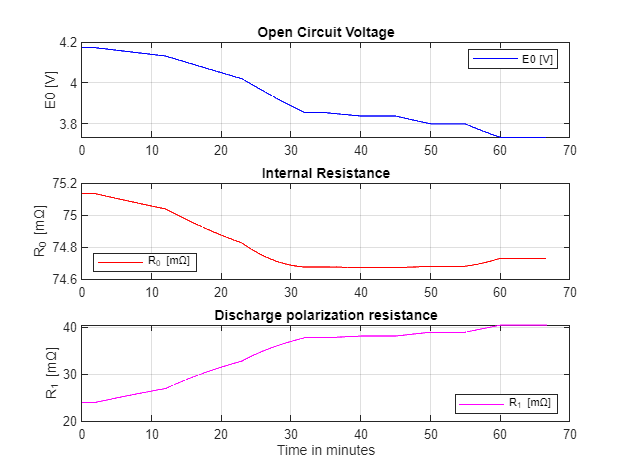

t_sec = Data.tout;
SoC_1 = getdatasamples(Data.SoC,(1:length(t_sec)));
E0 = getdatasamples(Data.E0,(1:length(t_sec)));
R0 = getdatasamples(Data.R0,(1:length(t_sec)));
R1 = getdatasamples(Data.R1,(1:length(t_sec)));
V_model = getdatasamples(Data.V_model,(1:length(t_sec)));

figure(2)
set(gcf,'color','w');
subplot(3,1,1)
    plot(t_sec/60,E0, 'b')
    %plot(I, 'r')
    hold on
    grid on
    legend('E0 [V]')
    legend('Location','northeast')
    title('Open Circuit Voltage')
    ylabel('E0 [V]')
    %xlabel('Time in minutes')
subplot(3,1,2)
    plot(t_sec/60,R0*1000, 'r')
    %plot(SoC*100, 'm')
    hold on
    grid on
    legend('R_{0} [mΩ]')
    legend('Location','southwest')
    title('Internal Resistance')
    ylabel('R_{0} [mΩ]')
    %xlabel('Time in minutes')
subplot(3,1,3)
    plot(t_sec/60, R1*1000, 'm')
    hold on
    grid on
    legend('R_{1} [mΩ]')
    legend('Location','southeast')
    title('Discharge polarization resistance')
    ylabel('R_{1} [mΩ]')
    xlabel('Time in minutes')

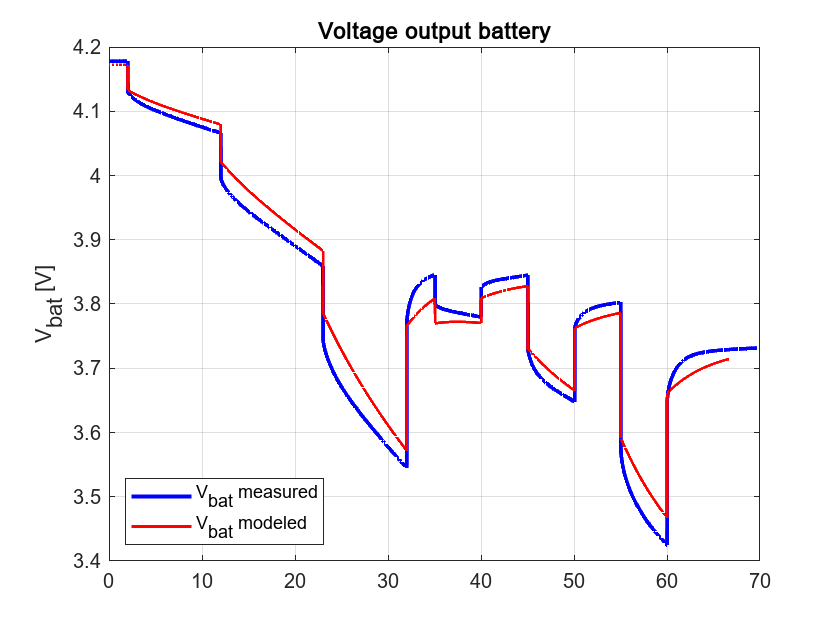



figure(3)
set(gcf,'color','w');
plot(time/60, V, 'LineWidth',2,'Color','b')
hold on
grid on
plot(t_sec/60, V_model, 'LineWidth', 1.5,'Color','r')
legend('V_{bat} measured','V_{bat} modeled')
legend('Location','southwest')
title('Voltage output battery')
ylabel('V_{bat} [V]')

## 3. Comparison with internal resistance model

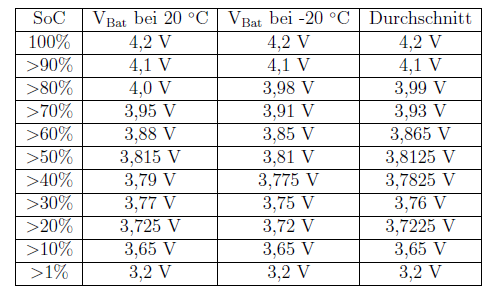

Using the model with a simple internal resistance

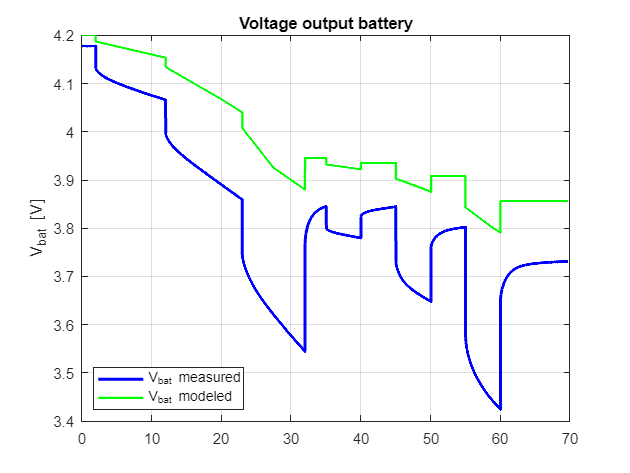

SoC_2=1:-0.1:0;
OCV=[4.2 4.1 3.99 3.93 3.865 3.8125 3.7825 3.76 3.7225 3.65 3.2];

%vq = interp1(x,v,xq)
OCVq = interp1(SoC_2,OCV,SoC);

%%OCV = V_Bat + I * RBat         (1)
%%RBat = ( 25 + 0.2 * (TBat - 20)^2 ) / 1000      (2)
Rbat = 0.025;   %miliOhm
V_batq = OCVq - I*Rbat;
% plot(time/60,V_batq, 'b')

figure(4)
set(gcf,'color','w');
plot(time/60, V, 'LineWidth',2,'Color','b')
hold on
grid on
plot(time/60, V_batq, 'LineWidth', 1.5,'Color','g')
legend('V_{bat} measured','V_{bat} modeled')
legend('Location','southwest')
title('Voltage output battery')
ylabel('V_{bat} [V]')

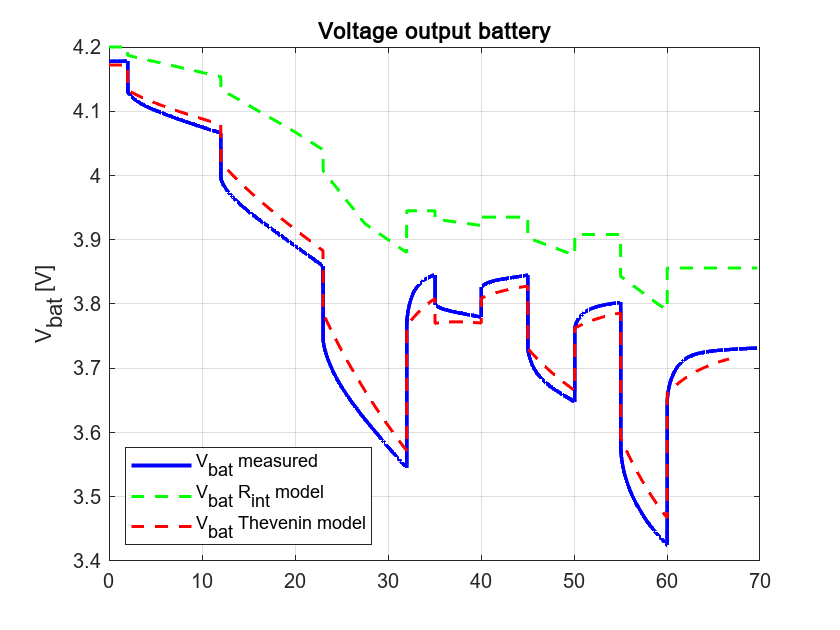



figure(5)
set(gcf,'color','w');
plot(time/60, V, 'LineWidth',2 ,'Color','b')
hold on
grid on
plot(time/60, V_batq, '--', 'LineWidth', 1.5,'Color','g')
plot(t_sec/60, V_model, '--', 'LineWidth', 1.5,'Color','r')
legend('V_{bat} measured','V_{bat} R_{int} model','V_{bat} Thevenin model')
legend('Location','southwest')
title('Voltage output battery')
ylabel('V_{bat} [V]')

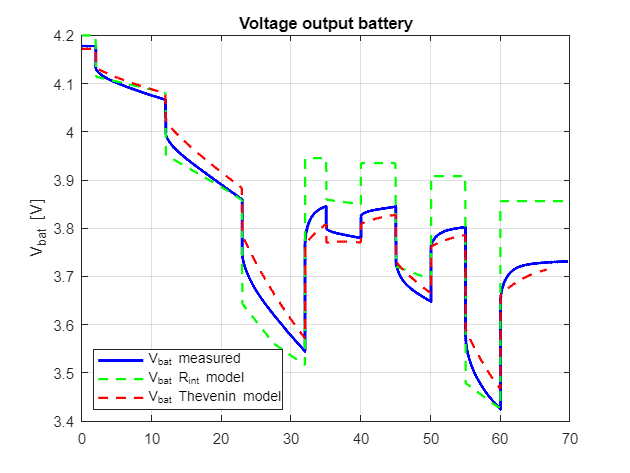

close all
SoC_2=1:-0.1:0;
OCV=[4.2 4.1 3.99 3.93 3.865 3.8125 3.7825 3.76 3.7225 3.65 3.2];

%vq = interp1(x,v,xq)
OCVq = interp1(SoC_2,OCV,SoC);

%%OCV = V_Bat + I * RBat         (1)
%%RBat = ( 25 + 0.2 * (TBat - 20)^2 ) / 1000      (2)
Rbat = 0.165;   %miliOhm
V_batq = OCVq - I*Rbat;
figure(6)
set(gcf,'color','w');
plot(time/60, V, 'LineWidth',2 ,'Color','b')
hold on
grid on
plot(time/60, V_batq, '--', 'LineWidth', 1.5,'Color','g')
plot(t_sec/60, V_model, '--', 'LineWidth', 1.5,'Color','r')
legend('V_{bat} measured','V_{bat} R_{int} model','V_{bat} Thevenin model')
legend('Location','southwest')
title('Voltage output battery')
ylabel('V_{bat} [V]')

## 4. Low Temperature model

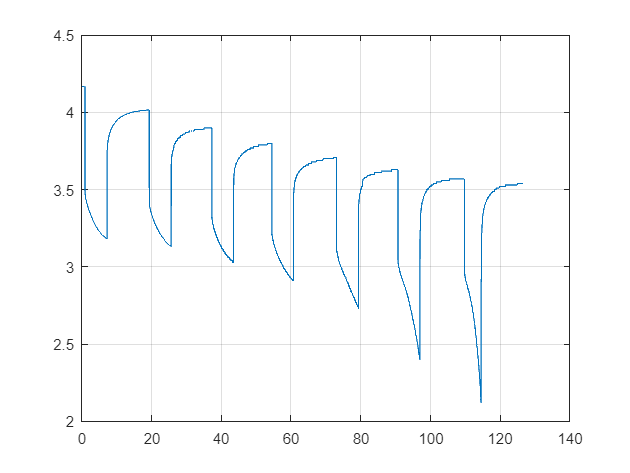

clear all
close all
load batpulsemeasLowTemp.mat

Iplt = 2.5;   % Ah
E0lt =       [ 4.16874  4.01642  3.9000  3.8  3.71 3.63 3.57 ]; %V
Vs1lt =      [ 3.54646  3.50958  3.3300  3.23 3.12 3.04 2.98 ]; %V
deltaV0lt = E0lt - Vs1lt;
R0lt = deltaV0lt / Iplt;
%Temp0lt =
%Tempflt =
Vdislt =      [3.18251 3.13226 3.03 2.91 2.73 2.4];
for i=1:6
    deltaVinflt(1,i) = E0lt(i+1) - Vdislt (i);
end

R1lt = deltaVinflt/Iplt-R0lt(1:6);
v95lt = Vdislt + 0.99*deltaVinflt;
%tf=[ 1434 3610 5909 8064 10092 12354 ];
tf2=[ 1740 4099 6531 8759 10806 12989 ];
t0=[ 901  3173 5403 7525 9836  12013];
tau5=(tf2-t0)/2.066; % deltatinflt =
C1lt = (tau5/5)./R1lt;

timelt=(1:1:length(samples))/2.066;
figure(7)
    set(gcf,'color','w');
    plot(timelt/60,voltagem)
    grid on

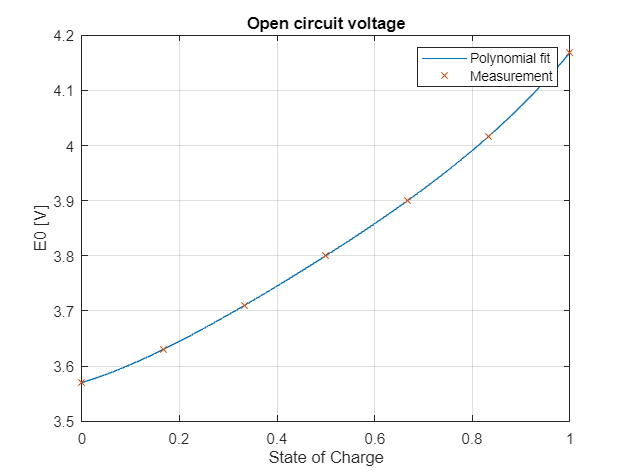

%% E0

SoClt = [1.0 5/6 4/6 3/6 2/6 1/6 0]';
%E0 = [4.174	4.0437	3.93536	3.83785	3.73929	3.67334	3.63052	3.59078	3.51287	3.43506]';
E0lt=E0lt';
X = [ones(size(SoClt)) SoClt  (SoClt).^2 (SoClt).^3 (SoClt).^4];
p2 = X\E0lt;


SoCd = [0.0:0.01:1];
%E0d=p(1)*SoCd.^4+p(2)*SoCd.^3+p(3)*SoCd.^2+p(4)*SoCd+p(5);
%E0d=p(1)*SoCd.^3+p(2)*SoCd.^2+p(3)*SoCd.^1+p(4);
%E0d=p(1)*SoCd.^2+p(2)*SoCd.^1+p(3);
E0d=p2(5)*SoCd.^4+p2(4)*SoCd.^3+p2(3)*SoCd.^2+p2(2)*SoCd+p2(1);

pt= [0 1.05 -2.11 2.45 2.8];
E0t=pt(1)*SoCd.^4+pt(2)*SoCd.^3+pt(3)*SoCd.^2+pt(4)*SoCd+pt(5);
%plot(SoCd,E0t)

figure(8)
set(gcf,'color','w');
plot(SoCd,E0d)
hold on, grid on
plot(SoClt,E0lt,'x')
title('Open circuit voltage')
xlabel('State of Charge')
ylabel('E0 [V]')
legend('Polynomial fit','Measurement')

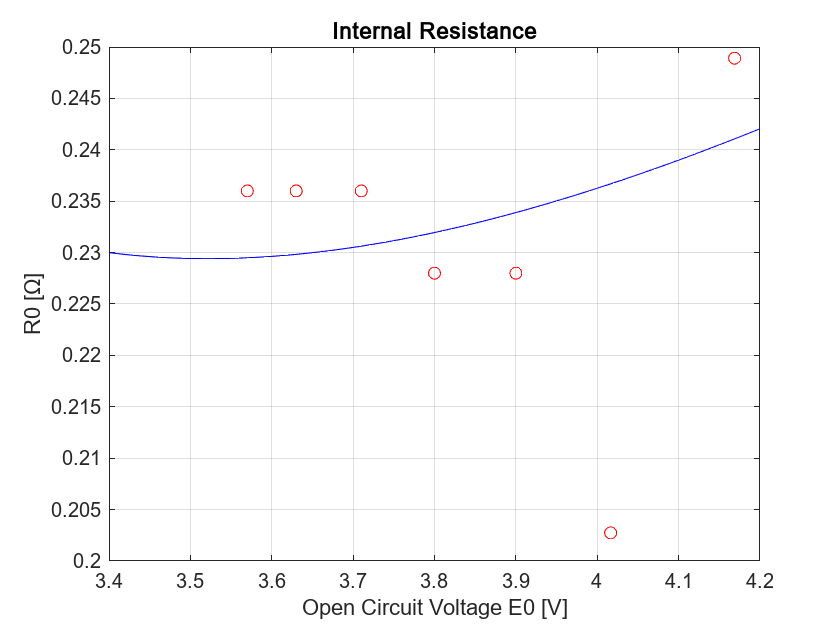

%% R0
%E0lt = ...
R0lt = R0lt';

X = [ones(size(E0lt)) E0lt  (E0lt).^2 ];

r = X\R0lt;

E0d = (3.4:0.01:4.2)';
R0d = [ones(size(E0d))  E0d  (E0d).^2]*r;
%rd=[0.0525 0.005 0.004 -2 3.6];
%rd=[0.22 0.05 0.04 -1.5 3.4];
rd=[0.020 0.05 0.04 -1.5 3.4];
R0t = rd(1)+rd(2)*E0d+rd(3)*exp(rd(4)*(E0d-rd(5)));

figure(9)
    set(gcf,'color','w');
%plot(E0d,R0d,'-',E0,R0,'o'), grid on, hold on
    plot(E0lt,R0lt,'or'), grid on, hold on
%plot(SoC,R0,'or'), grid on, hold on
    plot(E0d,R0t,'b')
%plot(SoCd,R0t,'b')
    title('Internal Resistance')
    xlabel('Open Circuit Voltage E0 [V]')
    ylabel('R0 [Ω]')
    xlim ([3.4 4.2])

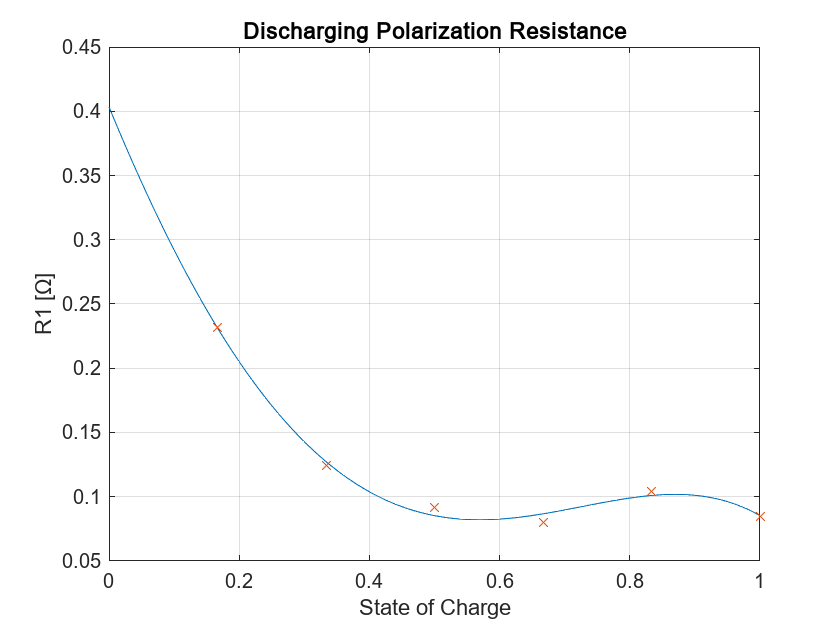

%% R1
%clear all
%SoClt = ...
SoC = SoClt(1:6);
R1lt= R1lt';

%[q,S,mu] = polyfit(SoC,R1,4)
X = [ones(size(SoC)) SoC  (SoC).^2 (SoC).^3 (SoC).^4];
q = X\R1lt;


SoCd = [0.0:0.01:1];
R1d=q(5)*SoCd.^4+q(4)*SoCd.^3+q(3)*SoCd.^2+q(2)*SoCd+q(1);

pt= [4.4 -10.39 8.47 -2.94 0.48];
E0t=pt(1)*SoCd.^4+pt(2)*SoCd.^3+pt(3)*SoCd.^2+pt(4)*SoCd+pt(5);

%plot(SoCd,E0t)

figure(10)
set(gcf,'color','w');
plot(SoCd,R1d)
hold on
grid on
plot(SoC,R1lt,'x')
%plot(SoCd,E0t,'g')
title('Discharging Polarization Resistance')
xlabel('State of Charge')
ylabel('R1 [Ω]')

# Simulation charge discharge

lets join everything

Modeling the behaviour of the model to compare with the measurements

clear all
close all

%%Parameters
% ebat0 = 3.288;
% ebat1 = 1.813;
% ebat2 = -4.205;
% ebat3 = 5.306;
% ebat4 = -2.03;
C = 7240;
R2 = 0.01968;
SoC_t0=0.9;

%current
%timeI = 1:1:9638;
timeI = 1:1:15E3;
%I=zeros(1,9638);
I=zeros(1,15E3);
for i=250:1491
    I(i)=0.52;
end
for i=1492:2854
    I(i)=1.3;
end 
for i=2855:3968
    I(i)=2.6;
end 
for i=4347:4962
    I(i)=0.52;
end 
for i=5581:6206
    I(i)=1.3;
end 
for i=6818:7438
    I(i)=2.6;
end 
for i=8639:9638
    I(i)=-2.6;
end 


%OVERWRITES THE PREVIOUS I
for i=250:1491
    I(i)=0.52;
end
for i=1492:2854
    I(i)=-1.3;
end 
for i=2855:3968
    I(i)=2.6;
end 
for i=4347:4962
    I(i)=-0.52;
end 
for i=5581:6206
    I(i)=1.3;
end 
for i=6818:7438
    I(i)=-2.6;
end 
for i=8639:9638
    I(i)=2.6;
end 

Data=sim('batterydischargev2');